# Optimization (minimum search)

This script is intended to introduce optimization by minimum search in Matlab.

## One dimensional function

Let's find the minimum of the following function:$f(x) = x^2 - 8x + 15$. The exact solution is $x_{min} = \arg \min f(x) = 4$.

The [fminsearch](https://www.mathworks.com/help/matlab/ref/fminsearch.html) function obtains numerically the minimum of a function given by its handle (function handle).

Creating handle of the function above with handle parameter corresponding to the $x$ independent variable of the function:

quadraticFcnHandle = @(x) x.^2 - 8 * x + 15;

Defining the initial point of from what the searching starts:

initialX = 0;

Performing minimum search:

[xMinQuadratic, minValueQuadratic] = fminsearch(quadraticFcnHandle, initialX);

The `fminsearch` function has several [options](https://www.mathworks.com/help/matlab/ref/fminsearch.html#bvadxhn-1-options) with which one can set the tolerance (fitness) of the solution or display information about the state of the solver. For example let's display the fitness of each iteration:

optimOptions = optimset('Display','iter');
fminsearch(quadraticFcnHandle, initialX, optimOptions);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1               15         
     1            2           14.998         initial simplex
     2            4           14.994         expand
     3            6           14.986         expand
     4            8            14.97         expand
     5           10          14.9381         expand
     6           12          14.8742         expand
     7           14           14.747         expand
     8           16          14.4941         expand
     9           18          13.9943         expand
    10           20          13.0194         expand
    11           22          11.1679         expand
    12           24          7.85806         expand
    13           26          2.81128         expand
    14           28        -0.990832         expand
    15           30        -0.990832         contract inside
    16           32        -0.990832         contract inside
    17           34        -0.990832  

xVect = 0 : 0.01 : 8;
yVect = quadraticFcnHandle(xVect);

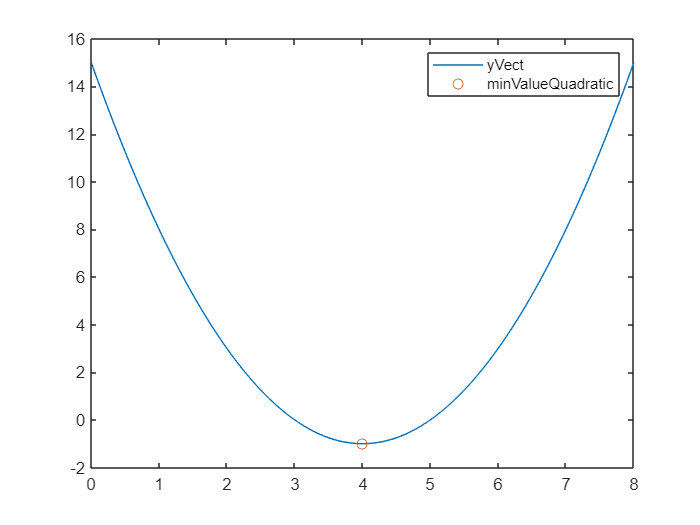

figure
% Create plot of xVect and yVect
plot(xVect,yVect,'DisplayName','yVect');

hold on
% Create scatter of xMinQuadratic and minValueQuadratic
scatter(xMinQuadratic,minValueQuadratic,'DisplayName','minValueQuadratic');
hold off

legend

## Multidimensional function

Let's find the minimum of a [Rosenbrock function](https://en.wikipedia.org/wiki/Rosenbrock_function) that has the following generic form: $f(x,y) = (a - x)^2 + b(y - x^2)^2 $ with $a$ and $b$ paramters. We implement the function in a separate file: [`genericRosenbrock.m`](http://genericrosenbrock.m)

In the case of multidimensional functions, the `fminsearch` works in the same way, but the independent variables of the function along which the minimum is searched have to be put into a vector. 

Let's create the function handle of a Rosenbrock function with $a = 1$ and $b = 100$ parameters:

aParam = 1;
bParam = 100;
rosenbrockFcnHandle = @(xValues, yValues) genericRosenbrock(xValues, yValues, aParam, bParam);

Unfortunately, the `fminsearch `function cannot handle the independent function variables in separate function handle parameters, instead they must be put into a vector as:

optimFcnHandle = @(xyValues) rosenbrockFcnHandle(xyValues(1), xyValues(2));

The initial point of the minimum search has to have as many elements as the number of independent variables:

initialPoint = [0, 0];
[xyMinRosenbrock, minValueRosenbrock] = fminsearch(optimFcnHandle, initialPoint);

### Visualization

Let's visualize the 2D Rosenbrock with a surface over the $x-y$ plane and the minimum place of the function!

The two-dimensional functions can be visualized by Matlab [surf](https://www.mathworks.com/help/matlab/ref/surf.html) command. First, the grid representation of the $x-y$ plane must be created by [meshgrid](https://www.mathworks.com/help/matlab/ref/meshgrid.html) function: 

xVect = -10 : 0.01 : 10;
yVect = -10 : 0.1 : 10;
[xGrid, yGrid] = meshgrid(xVect, yVect);

The variables `xGrid` and `yGrid` are matrices with as many rows and columns as many elements are in `xVect` and `yVect`, respectively. The corresponding elements of `xGrid` and `yGrid `represent the $x-y$ coordinates of a grid point.

Let's compute the $z =f(x,y)$ values of the Rosenbrock function above by evaluation the function handle in the pre-defined grid points:

zValuesRosenbrock = rosenbrockFcnHandle(xGrid, yGrid);

Now, we can visualize the surface of the Rosenbrock function above the $x-y$ plane:

figureObject = figure;
axisObject = axes(figureObject);
surf(axisObject, xGrid, yGrid, zValuesRosenbrock, 'EdgeColor', 'none');

Let's visualize the minimum point of the function with [3D scatter plot](https://www.mathworks.com/help/matlab/ref/scatter3.html): 

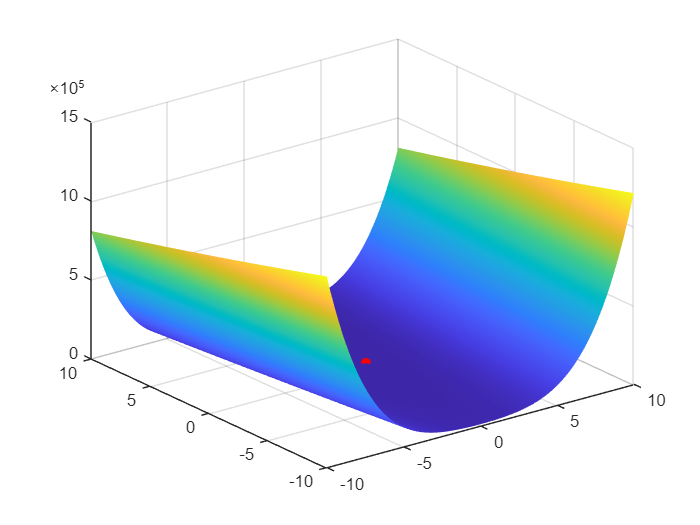

hold(axisObject, 'on')
scatter3(axisObject, xyMinRosenbrock(1), xyMinRosenbrock(2), minValueRosenbrock, 'red', 'filled')
hold(axisObject, 'off')